
clear all;
close all;
path = 'D:\MATLAB_Git\MATLAB-atomic-calculation\Monopole-dipole\';
addpath(path);
path_curve = 'D:\MATLAB_Git\MATLAB-atomic-calculation\Monopole-dipole\curve\';
curve1 = load([path_curve,'he.txt']);
curve2 = load([path_curve,'Maglab1.txt']);
curve3 = load([path_curve,'NG.txt']);
curve4 = load([path_curve,'PTB.txt']);



multiplier = 1.2;
lambda0 = 15;   % um, lambda min
lambdaFinal = 50;   % um, lambda max
len = floor(log(lambdaFinal/lambda0)/log(multiplier))+1;
zMin = [100-13.7*1];%um
zMax = 100+13.7*2;
mass_length = 1000;%um
mass_span = 500; %um; Along k vector;

atoms_length = 40; %um; Atom along k vector
atoms_width = 20; %um; along Beam waist
sample = 20;

xmin = 10e-6;
xmax = 200e-6;
ymin = 1e-24;
ymax = 3e-17;



geo = zeros(length(zMin),len,sample);
for j=1:length(zMin)
    for k=1:len
        lambda(k) = lambda0*multiplier^(k-1);
        sum=0;
        for i=1:sample
            x0=randn*atoms_length/2;
            y0=randn*atoms_width/2;
            z0=randn*atoms_width/2;
            geo(j,k,i) = ...
                geofactor(lambda(k),zMin(j),x0,y0,z0,mass_length,mass_span)-...
                geofactor(lambda(k),zMax,x0,y0,z0,mass_length,mass_span);
        end    
        k
    end
end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

g_factor=mean(geo,3);
g_error=std(geo,0,3)./sqrt(sample-1);
g_factor=g_factor*10^(-6);
g_error=g_error*10^(-6);



% omega1 = 2*pi*9.2318;
% omega2 = 2*pi*12.8177;
omega1 = 2*pi*9.2318*2;
omega2 = 2*pi*12.8177*2;

%deltaX = 2*pi*10e-5; %3hours
%deltaX = 2*pi*60e-6;   % test 1 day 2 sigma
deltaX = 4.3e-5*omega2;

%deltaX = 2*pi/sqrt(1000*28*10*20)/15;%100 hours
hbar = 6.6260755e-34/(2*pi);%Constant.ReducedPlanck;
Na=Constant.AvogadroNumber;
mn=Constant.AtomicMass;
rho_pt=21.45; % g/cm^3
n=rho_pt/1000/mn*10^6; % /m^3

c1=-1/3;
c2=1/5;


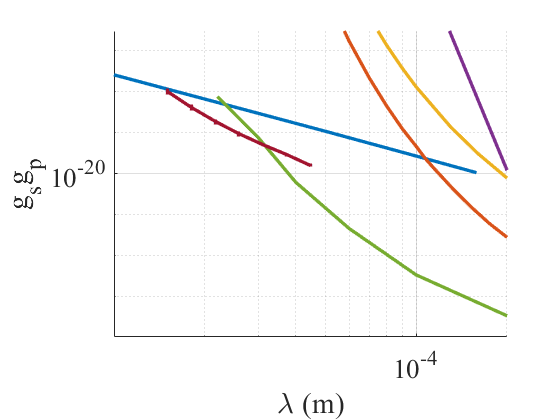


f1 = figure; hold on;
lw = 2.5;
plot(curve1(:,1),curve1(:,2),'LineWidth',lw);
plot(curve2(:,1),curve2(:,2),'LineWidth',lw);
plot(curve3(:,1),curve3(:,2),'LineWidth',lw);
plot(curve4(:,1),curve4(:,2),'LineWidth',lw);
load('ning_data.mat');
plot(ning_data(:,1),ning_data(:,2)*1.5,'LineWidth',lw);

for i=1:length(zMin)
    gsgp(:)=deltaX./(hbar*n*(c1*omega2-c2*omega1)./(8*pi*mn*omega2).*g_factor(i,:));
    gsgp_error(:)=deltaX./(hbar*n*(c1*omega2-c2*omega1)./(8*pi*mn*omega2).*g_factor(i,:).^2).*g_error(i,:);
    l=plot(lambda.*10^(-6),abs(gsgp),'.-');
    l=errorbar(lambda.*10^(-6),abs(gsgp),gsgp_error);
    set(l,'linewidth',lw,'CapSize',0,'MarkerSize',2);
end

set(gca,'XScale','log','YScale','log','fontsize',20)
set(gca,'fontname','times new roman')
xlabel('\lambda (m)')
ylabel('g_sg_p')

%legend('3um','5um')
xlim([xmin xmax]);
ylim([ymin ymax]);
grid on;

set(f1,'Visible','on');


%save([path,'100um.mat']);
%saveas(f1,[path,'100um.png']);
%savefig(f1,[path,'100um.fig']);


function output = geofactor(lambda,zMin,x0,y0,z0,mass_length,mass_span)
    fun = @(x,y,z) (1./(distance(x,y,z,x0,y0,z0).*lambda) + 1./distance(x,y,z,x0,y0,z0).^2).*...
    exp(-distance(x,y,z,x0,y0,z0)./lambda).*z./distance(x,y,z,x0,y0,z0);
    output = integral3(fun,-mass_span/2,mass_span/2,-mass_length/2,mass_length/2,zMin,zMin+mass_length);
end


function output = distance(x1,y1,z1,x2,y2,z2)
    output = sqrt((x1-x2).^2+(y1-y2).^2+(z1-z2).^2);
end
